# **Week L5: Examining Non-Linear Effects through the Manakov Equation**

The code below examines the non-linear effects in an optic fibre, in addition to attenuation and chromatic dispersion, through the solution of the Manakov equation using the split-step Fourier method

## **Transmitter**

The model of the transmitter consists of the following elements:

- A symbol generator which modulates source bits using QPSK.

- An IQ modulator which modulates the output of a laser according to an electrical signal.

### Modulation

clearvars;

% Parameters
NSymb = 10000; % No. of symbols 
SpS = 8; % Samples per symbol
Rs = 50e9; % Symbol rate in symbols/sec
SNR_vals = [0:1:10];
laserPw_dBm = [-20:4:20];
T = 1/(SpS*Rs); % Sampling period in s
t= [0:NSymb*SpS - 1]*T; % Time vector for plotting time-series data

% FOR QPSK:
% Generating random bit sequence(s)
sourceBitsQPSK = randi([0 1], NSymb*2, 2); % Matrix of source bits for QPSK
sourceIntsQPSK = bit2int(sourceBitsQPSK, 2); % Vector of source bits converted to ints
sourceSymbolsQPSK = pskmod(sourceIntsQPSK, 4, pi/4); % Maps source bit vector to symbol vector

% Modulating voltage with generated symbols
vI_QPSK = real(sourceSymbolsQPSK);
vQ_QPSK = imag(sourceSymbolsQPSK);

vI_QPSK_upsampled = repelem(vI_QPSK, SpS, 1); % Upsampling according to SpS
vQ_QPSK_upsampled = repelem(vQ_QPSK, SpS, 1); % Upsampling according to SpS

% Visualising in-phase and quadrature voltage
% stairs(t(1:10*SpS), vI_QPSK_upsampled(1:10*SpS,1,1), "o-");
% hold on
% stairs(t(1:10*SpS), vQ_QPSK_upsampled(1:10*SpS,1,1), "o-");
% title("Modulated Voltage")
% xlabel("Time / s")
% ylabel("Voltage / V")
% legend("In-phase", "Quadrature")
% grid on
% hold off

### Pulse Shaping

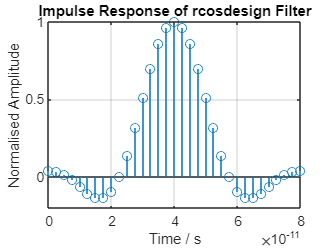

% RRC filter parameters
filterSpan = 4; % Span of RRC filter in no. of symbols
rollOff = 0.5;
filterResponse = rcosdesign(rollOff, filterSpan, SpS)'; filterResponse = filterResponse*(1/max(filterResponse));
samples = 1+(NSymb-1)*SpS + filterSpan*SpS;
v_shaped_t = [0:1:samples-1]*T;

% Visualisation of RRC filter
filterResponse_t = [0:1:filterSpan*SpS]*T; % time vector for the filter response
% filterResponse_t_interp = [0:0.25:filterSpan*SpS]*T;
% filterResponse_interp = interp1(filterResponse_t, filterResponse, filterResponse_t_interp, "spline");
% plot(filterResponse_t, filterResponse, "o", filterResponse_t_interp, filterResponse_interp, ":.");
stem(filterResponse_t, filterResponse, '-o');
title('Impulse Response of rcosdesign Filter');
xlabel('Time / s');
ylabel('Normalised Amplitude');
grid on

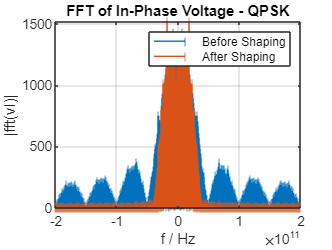


% ---------------------------------------------------------------------------

% FOR QPSK:
% Using RRC filter to shape vI and vQ
vI_QPSK_shaped = upfirdn(vI_QPSK, filterResponse, SpS, 1); vQ_QPSK_shaped = upfirdn(vQ_QPSK, filterResponse, SpS, 1);


% Frequency spectrum of voltage waveforms before filtering
fft_vI_QPSK = fftshift(fft(real(vI_QPSK_upsampled(:,1)))); % FFT of signal before shaping
freqArr = [-NSymb*SpS/2:NSymb*SpS/2 - 1]/(T*NSymb*SpS);

fft_vI_QPSK_shaped = fftshift(fft(vI_QPSK_shaped(:,1))); % FFT of signal after shaping
freqArr_shaped = [-samples/2:samples/2 - 1]/(T*samples);

stem(freqArr, abs(fft_vI_QPSK), "|");
hold on
stem(freqArr_shaped, abs(fft_vI_QPSK_shaped), "|");
title("FFT of In-Phase Voltage - QPSK");
xlabel("f / Hz");
ylabel("|fft(vI)|");
legend("Before Shaping", "After Shaping");
hold off
grid on


% Visualising pulse-shaped voltages
% plot(v_shaped_t(1:10*SpS + filterSpan), vI_QPSK(1:10*SpS + filterSpan,1), "o-");
% hold on
% plot(v_shaped_t(1:10*SpS + filterSpan), vI_QPSK_shaped(1:10*SpS + filterSpan,1), "o-");
% title("Shaped In-Phase Voltage - QPSK");
% ylabel("Voltage / V");
% xlabel('Time / s');
% legend("Before shaping", "After shaping");
% grid on
% hold off

bandwidth = 0.5*(1+rollOff)/T

bandwidth = 3.0000e+11

### IQ Modulation

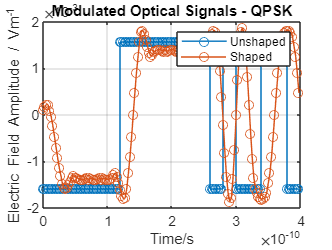

% Initialising laser parameters
lineWidth = 0;
laserPw_Lin = (1e-3)*10.^(laserPw_dBm/10);

% Modulating optical signals using IQM
Vpi = pi/2; % Voltge required to change phase of E-field by pi

modOpticSigQPSK = zeros(size(vI_QPSK_upsampled,1), 2, length(laserPw_dBm));
modOpticSigQPSK_shaped = zeros(size(vI_QPSK_shaped,1), 2, length(laserPw_dBm));

for i=1:length(laserPw_dBm)
    % Generating output from laser modelled as a continuous-wave source
    laserE = Laser(laserPw_dBm(i), lineWidth, SpS, Rs, NSymb, 2); % Laser output to be used with unshaped signals
    laserE_shaped = Laser(laserPw_dBm(i), lineWidth, SpS, Rs, samples/SpS, 2); % Laser output to be used with shaped signals

    % For QPSK:
    modOpticSigQPSK(:,:,i) = (vI_QPSK_upsampled+1i*vQ_QPSK_upsampled).*laserE; % Unshaped
    modOpticSigQPSK_shaped(:,:,i) = (vI_QPSK_shaped+1i*vQ_QPSK_shaped).*laserE_shaped; % Shaped
end

% Test signals
testQPSK = (vI_QPSK_upsampled+1i*vQ_QPSK_upsampled).*laserE;

% Visualising modulated optical signals
% For QSPK:
stairs(t(1:20*SpS), real(modOpticSigQPSK(1:20*SpS,1,1)), "o-");
hold on
plot(t(1:20*SpS), real(modOpticSigQPSK_shaped(1+filterSpan:filterSpan+20*SpS,1,1)), "o-");
title("Modulated Optical Signals - QPSK")
xlabel("Time/s")
ylabel("Electric Field Amplitude / Vm^{-1}")
legend("Unshaped", "Shaped")
grid on
hold off

## Optical Channel

### Adding Attenuation, CD and/or Non-Linear Effects through the NLSE

Ls = 80; % Length of span in km
Ns = 1; % No. of spans
fibreParams = struct("alpha", 0.2, "gamma", 1.3, "linkLength", Ns*Ls, "D", 17); % Fibre parameters to be used in the SSFM
stepSize = 1; % Step size for SSF method in km
CLambda = 1550e-9; % Central wavelength of optical carrier in m

% Initialising channel outputs
channelOutQPSK = zeros(size(modOpticSigQPSK));
channelOutQPSK_shaped = zeros(size(modOpticSigQPSK_shaped));

% Solving the Manakov Equation using the SSF method
for i=1:length(laserPw_dBm)
    channelOutQPSK(:,:,i) = SplitStepFourier(modOpticSigQPSK(:,:,i), SpS, Rs, CLambda, fibreParams, stepSize, 2); % Unshaped
    channelOutQPSK_shaped(:,:,i) = SplitStepFourier(modOpticSigQPSK_shaped(:,:,i), SpS, Rs, CLambda, fibreParams, stepSize, 2); % Shaped
end

% Amplfier gain
channelOutQPSK = channelOutQPSK*exp(Ns*Ls*fibreParams.alpha*log(10)/20);
channelOutQPSK_shaped = channelOutQPSK_shaped*exp(Ns*Ls*fibreParams.alpha*log(10)/20);
% -------------------------------------------------------------------------------------------

% Only adding non-linear distortion (i.e. no attenuation or CD)
% for i=1:length(laserPw_dBm)
%     channelOutQPSK(:,i) = modOpticSigQPSK(:,i); channelOutQPSK_shaped(:,i) = modOpticSigQPSK_shaped(:,i);
%     for j=1:fibreParams.linkLength
%         channelOutQPSK(:,i) = exp(-1i*stepSize*fibreParams.gamma*abs(channelOutQPSK(:,i)).^2).*channelOutQPSK(:,i);
%         channelOutQPSK_shaped(:,i) = exp(-1i*stepSize*fibreParams.gamma*abs(channelOutQPSK_shaped(:,i)).^2).*channelOutQPSK_shaped(:,i);
%     end
% end

% -------------------------------------------------------------------------------------------

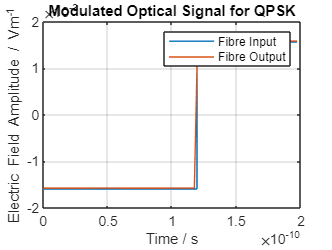

% Visualising optical signals before and after noise and attenuation

% QPSK unshaped
stairs(t(1:10*SpS), real(modOpticSigQPSK(1:10*SpS,1,1)), "-"); 
hold on
plot(t(1:10*SpS), real(channelOutQPSK(1:10*SpS,1,1)), "-");
xlabel("Time / s"); 
ylabel("Electric Field Amplitude / Vm^{-1}")
title("Modulated Optical Signal for QPSK")
legend("Fibre Input", "Fibre Output")
grid on
hold off

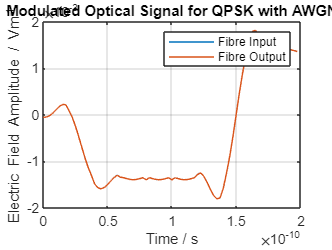


% QPSK shaped
plot(t(1:10*SpS), real(modOpticSigQPSK_shaped(1:10*SpS,1,1)), ""); 
hold on
plot(t(1:10*SpS), real(channelOutQPSK_shaped(1:10*SpS,1,1)), "-");
xlabel("Time / s"); 
ylabel("Electric Field Amplitude / Vm^{-1}")
title("Modulated Optical Signal for QPSK with AWGN")
legend("Fibre Input", "Fibre Output")
grid on
hold off


% Non-linear phase variation
Leff = (1-exp(-fibreParams.alpha*log(10)*Ls*Ns/10))/(fibreParams.alpha*log(10)/10)

Leff = 21.1693

phiNLI = (8/9)*(fibreParams.gamma*Leff*laserPw_Lin)*180/pi

phiNLI =     0.0140    0.0352    0.0884    0.2221    0.5580    1.4016    3.5206    8.8434   22.2136   55.7981  140.1585


phiNLI_unshaped = reshape(mean(angle(channelOutQPSK(:,1,:))-angle(modOpticSigQPSK(:,1,:)))*180/pi,1,length(laserPw_dBm))

phiNLI_unshaped =    -0.0143   -0.0360   -0.0905   -0.2273   -0.5709   -1.4341   -3.6023   -9.0486  -22.7290   32.3312   38.2455


phiNLI_shaped = reshape(mean(angle(channelOutQPSK_shaped(:,1,:))-angle(modOpticSigQPSK_shaped(:,1,:)))*180/pi,1,length(laserPw_dBm))

phiNLI_shaped =     0.6322    0.6155    0.5734    0.4676    0.2020   -0.4652   -2.1411   -6.2384  -14.8470    5.5341   -1.9171


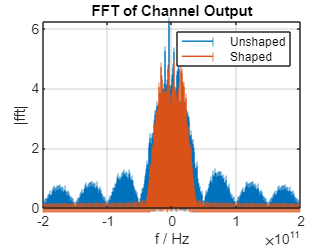


% Evaluating and visualising spectra at fibre output
fft_channelOut = fftshift(fft(channelOutQPSK(:,1,1))); % FFT of unshaped channel output
fft_channelOut_shaped = fftshift(fft(channelOutQPSK_shaped(:,1,1))); % FFT of shaped channel output

stem(freqArr, abs(fft_channelOut), "|");
hold on
stem(freqArr_shaped, abs(fft_channelOut_shaped), "|");
title("FFT of Channel Output");
xlabel("f / Hz");
ylabel("|fft|");
legend("Unshaped", "Shaped");
hold off
grid on

% Testing accuracy of SSFM:

% From book:
Bref = 12.5e9 % Reference bandwidth for OSNR calculations

Bref = 1.2500e+10

B_WDM = bandwidth % Bandwidth

B_WDM = 3.0000e+11

alpha_Np = fibreParams.alpha*log(10)/10

alpha_Np = 0.0461

L_eff = 1/alpha_Np % Effective Length

L_eff = 21.7147

beta2 = fibreParams.D/0.784

beta2 = 21.6837

F_dB = 5; F_Lin = 10^(F_dB/10) % Amplifier noise factor

F_Lin = 3.1623


c = 299792458; % Speed of light in m/s
h = 6.62607015e-34 % Plank's constant in Js

h = 6.6261e-34


eta_SS = 8*(fibreParams.gamma^2)*(L_eff^2)*alpha_Np*asinh((pi^2)*(beta2*10^-24)*(B_WDM^2)/(2*alpha_Np))*Bref/(27*pi*(beta2*10^-24)*Rs^3)

eta_SS = 96.3471

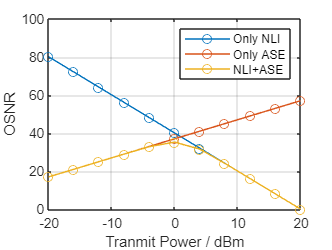


OSNR_NLI = laserPw_Lin./(Ns*eta_SS*laserPw_Lin.^3);
OSNR_ASE = laserPw_Lin./(F_Lin*Ns*(exp(alpha_Np*Ls)-1)*h*(c/CLambda)*Bref);
OSNR_total = laserPw_Lin./((Ns*eta_SS*laserPw_Lin.^3) + (F_Lin*Ns*(exp(alpha_Np*Ls)-1)*h*(c/CLambda)*Bref));

plot(laserPw_dBm, 10*log10(OSNR_NLI), "-o")
hold on
plot(laserPw_dBm, 10*log10(OSNR_ASE), "-o")
plot(laserPw_dBm, 10*log10(OSNR_total), "-o")
xlabel("Tranmit Power / dBm")
ylabel("OSNR")
legend("Only NLI", "Only ASE", "NLI+ASE")
grid on
hold off


% --------------------------------------------------------------------------

laserPw_Lin

laserPw_Lin =     0.0000    0.0000    0.0001    0.0002    0.0004    0.0010    0.0025    0.0063    0.0158    0.0398    0.1000


sigPw = mean(abs(modOpticSigQPSK(:,1,:)).^2 + abs(modOpticSigQPSK(:,2,:)).^2); sigPw = reshape(sigPw,1,length(sigPw),1)

sigPw =     0.0000    0.0000    0.0001    0.0002    0.0004    0.0010    0.0025    0.0063    0.0158    0.0398    0.1000


sigPw_shaped = mean(abs(modOpticSigQPSK_shaped(:,1,:)).^2 + abs(modOpticSigQPSK_shaped(:,2,:)).^2); sigPw_shaped = reshape(sigPw_shaped,1,length(sigPw_shaped),1)

sigPw_shaped =     0.0000    0.0000    0.0000    0.0001    0.0003    0.0008    0.0019    0.0049    0.0123    0.0308    0.0773



% Evaluating non-linear noise power
nonLinearNoise = channelOutQPSK-modOpticSigQPSK; 
nonLinearNoise_shaped = channelOutQPSK_shaped-modOpticSigQPSK_shaped;

nonLinearNoisePw = mean(abs(nonLinearNoise(:,1,:)).^2 + abs(nonLinearNoise(:,2,:)).^2); nonLinearNoisePw = reshape(nonLinearNoisePw,1,length(laserPw_dBm),1)

nonLinearNoisePw =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0025    0.0364    0.3606


nonLinearNoisePw_shaped = mean(abs(nonLinearNoise_shaped(:,1,:)).^2 + abs(nonLinearNoise_shaped(:,2,:)).^2); nonLinearNoisePw_shaped = reshape(nonLinearNoisePw_shaped,1,length(laserPw_dBm),1)

nonLinearNoisePw_shaped =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0224    0.2294



% Estimating SNR using manually evaluated signal and noise powers
nonLinearSNR_manual = sigPw./nonLinearNoisePw

nonLinearSNR_manual = 1.0e+07 *

    1.5962    0.2530    0.0401    0.0064    0.0010    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000


nonLinearSNR_shaped_manual = sigPw_shaped./nonLinearNoisePw_shaped

nonLinearSNR_shaped_manual = 1.0e+07 *

    2.0146    0.3193    0.0506    0.0080    0.0013    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000


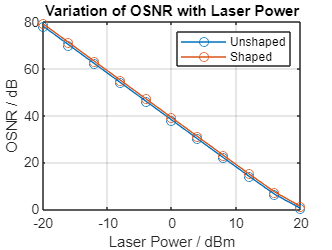


% Visualing simulated SNR variation
plot(laserPw_dBm, 10*log10(nonLinearSNR_manual*Rs/Bref), "-o");
hold on
plot(laserPw_dBm, 10*log10(nonLinearSNR_shaped_manual*Rs/Bref), "-o");
xlabel("Laser Power / dBm");
ylabel("OSNR / dB");
title("Variation of OSNR with Laser Power");
legend("Unshaped", "Shaped")
grid on
hold off

### Adding AWGN

% Adding AWGN
channelOutQPSK_AWGN = zeros(size(channelOutQPSK,1),size(channelOutQPSK,2), length(SNR_vals));
channelOutQPSK_shaped_AWGN = zeros(size(channelOutQPSK_shaped,1),size(channelOutQPSK_shaped,2), length(SNR_vals));
AWGNPw = zeros(length(laserPw_dBm),length(SNR_vals));
AWGNPw_shaped = zeros(length(laserPw_dBm),length(SNR_vals));
for i=1:length(laserPw_dBm)
    for j=1:length(SNR_vals)
        [channelOutQPSK_AWGN(:,i,j), AWGNPw(i,j)] = awgn(channelOutQPSK(:,i), convertSNR(SNR_vals(j),'ebno', samplespersymbol=1, bitspersymbol=2), 'measured'); % QPSK unshaped
        [channelOutQPSK_shaped_AWGN(:,i,j), AWGNPw_shaped(i,j)] = awgn(channelOutQPSK_shaped(:,i), convertSNR(SNR_vals(j),'ebno', samplespersymbol=2, bitspersymbol=2), 'measured'); % QPSK shaped
    end
end

% Manually evaluating the signal and noise powers
sigPw_beforeAWGN = var(channelOutQPSK, 0, 1)

sigPw_beforeAWGN =      0     0


sigPw_beforeAWGN_shaped = var(channelOutQPSK_shaped, 0, 1)

sigPw_beforeAWGN_shaped = 1.0e-05 *

    0.9455    0.9453


noisePw = zeros(length(SNR_vals), length(laserPw_dBm));
noisePw_shaped = zeros(length(SNR_vals), length(laserPw_dBm));
for i=1:length(SNR_vals)
    noisePw(i,:) = var(channelOutQPSK_AWGN(:,:,i)-channelOutQPSK,0,1);
    noisePw_shaped(i,:) = var(channelOutQPSK_shaped_AWGN(:,:,i)-channelOutQPSK_shaped,0,1);
end

Unable to perform assignment because the size of the left side is 1-by-1 and the size of the right side is 1-by-2.


sigPw_beforeAWGN./noisePw
sigPw_beforeAWGN_shaped./noisePw_shaped
% Visualing AWGN power variation
plot(SNR_vals, AWGNPw, "-o");
xlabel("SNR per bit / dB");
ylabel("Noise Power");
title("Variation of Noise Power with SNR - Unshaped");
grid on

plot(SNR_vals, AWGNPw_shaped, "-o");
xlabel("SNR per bit / dB");
ylabel("Noise Power");
title("Variation of Noise Power with SNR - Unshaped");
grid on


% ---------------------------------------------------------------------------------------------

% Evaluating variation of overall SNR with laserPower
% totalNoise = channelOutQPSK_AWGN - modOpticSigQPSK;
% totalNoise_shaped = channelOutQPSK_shaped_AWGN - modOpticSigQPSK_shaped;
% totalNoisePw = zeros(length(laserPw_dBm), length(SNR_vals));
% totalNoisePw_shaped = zeros(length(laserPw_dBm), length(SNR_vals));
% for i=1:length(SNR_vals)
%     totalNoisePw(:,i) = var(totalNoise(:,:,i), 0, 1).';
%     totalNoisePw_shaped(:,i) = var(totalNoise_shaped(:,:,i), 0, 1).';
% end

% plot(laserPw_dBm, 10*log10(laserPw_Lin'./totalNoisePw), "-o");
% xlabel("Laser Power / dBm");
% ylabel("SNR ");
% title("Variation of SNR with Laser Power - Unshaped");
% grid on
% 
% plot(laserPw_dBm, 10*log10(laserPw_Lin'./totalNoisePw_shaped), "-o");
% xlabel("Laser Power / dBm");
% ylabel("SNR ");
% title("Variation of SNR with Laser Power - Shaped");
% grid on


% Debugging addition of AWGN to the optical signal

% Calculating BERs for different SNR values
testBER = zeros(length(SNR_vals),1); testBER_shaped = zeros(length(SNR_vals),1);

for i=1:length(SNR_vals)
    testQPSK_AWGN_Ints = pskdemod(channelOutQPSK_AWGN(1:SpS:end,1,i), 4, pi/4); 
    testQPSK_AWGN_Bits = int2bit(testQPSK_AWGN_Ints, 2);
    [~, testBER(i,1)] = biterr(testQPSK_AWGN_Bits, sourceBitsQPSK(:,1)); % Unshaped
    
    testQPSK_shaped_AWGN_out = upfirdn(channelOutQPSK_shaped_AWGN(:,1,i),filterResponse, 1, SpS); 
    testQPSK_shaped_AWGN_out = testQPSK_shaped_AWGN_out(filterSpan+1 : end-filterSpan,:,:);
    testQPSK_shaped_AWGN_Ints = pskdemod(testQPSK_shaped_AWGN_out, 4, pi/4); 
    testQPSK_shaped_AWGN_Bits = int2bit(testQPSK_shaped_AWGN_Ints, 2);
    [~, testBER_shaped(i,1)] = biterr(testQPSK_shaped_AWGN_Bits, sourceBitsQPSK(:,1)); % Shaped
end

% Visualising symbol distribution
plot(channelOutQPSK_shaped_AWGN(:,1,1), '.');
hold on
plot(channelOutQPSK_shaped_AWGN(:,1,end), '.');
plot(sourceSymbolsQPSK(1:100,1)*sqrt(laserPw_Lin(1)), '+', LineWidth=2);
title("Symbol Distribution");
ylabel("Imaginary");
xlabel("Real");
legend("Min. SNR", "Max. SNR", "Original");
grid on
hold off

% Visualising BER vs SNR curves
semilogy(SNR_vals, 0.5*erfc(sqrt(10.^(SNR_vals/10))));
hold on
semilogy(SNR_vals, testBER', '*');
semilogy(SNR_vals, testBER_shaped', 'o');
title("BER vs. SNR for QPSK");
ylabel("BER");
xlabel("SNR per bit / dB");
legend("Theoretical", "Unshaped", "Shaped");
grid on
hold off

## Receiver

### Optical Front-End

% Generating Local optical signal for coherent detection
Elo = Laser(30, 0, SpS, Rs, NSymb, 1); % Identical to initial laser source
Elo_shaped = Laser(30, 0, SpS, Rs, samples/SpS, 1); % Identical to initial laser source

% Generating output from optical front-end
eta_ph = 0.3; % Responsivity of photodetectors

% Computing output from optical front-end 
% Signals with AWGN + varying laser powers
OpticFEOutQPSK = zeros(size(channelOutQPSK_AWGN,1), 2*size(channelOutQPSK_AWGN,2), size(channelOutQPSK_AWGN,3));
OpticFEOutQPSK_shaped = zeros(size(channelOutQPSK_shaped_AWGN,1), 2*size(channelOutQPSK_shaped_AWGN,2), size(channelOutQPSK_shaped_AWGN,3));
for i=1:length(SNR_vals) 
    count = 1;
    for j=1:length(laserPw_dBm) 
        % QPSK
        OpticFEOutQPSK(:,count:count+1,i) = OpticalFrontEnd(channelOutQPSK_AWGN(:,j,i), Elo, eta_ph, 1); % Unshaped
        OpticFEOutQPSK_shaped(:,count:count+1,i) = OpticalFrontEnd(channelOutQPSK_shaped_AWGN(:,j,i), Elo_shaped, eta_ph, 1); % Shaped
    
        count = count+2;
    end
end

% --------------------------------------------------------------------------------------------------

% Test signals
count=1;
for i=1:length(laserPw_dBm)
    % Test signals with no added AWGN
    testFEOutQPSK(:,count:count+1) = OpticalFrontEnd(testQPSK(:,i), Elo, eta_ph, 1);
    count = count+2;
end

% Visualising transmitted and received test signal
% stairs(t(1:10*SpS), testQPSK(1:10*SpS,1), "-o");
% hold on
% stairs(t(1:10*SpS), testFEOutQPSK(1:10*SpS,1)/eta_ph, "-o");
% xlabel("Time / s"); 
% ylabel("Electric Field Amplitude / Vm^{-1}")
% title("Modulated Optical Signal")
% legend("Transmitted", "Received")
% grid on
% hold off

% --------------------------------------------------------------------------------------------------

% TIA amplification and sampling using ADC
TIA_Gain = 1; % TIA amplification factor
Fs = SpS; % Sampling frequency of ADC

% Amplification and separation of in-phase and quadrature components
% QPSK
OpticFEOutQPSK_I = TIA_Gain*OpticFEOutQPSK(:, 1:2:end, :); OpticFEOutQPSK_Q = TIA_Gain*OpticFEOutQPSK(:, 2:2:end, :); % Unshaped
OpticFEOutQPSK_shaped_I = TIA_Gain*OpticFEOutQPSK_shaped(:, 1:2:end, :); OpticFEOutQPSK_shaped_Q = TIA_Gain*OpticFEOutQPSK_shaped(:, 2:2:end, :); % Shaped
testFEOutQPSK_I = TIA_Gain*testFEOutQPSK(:, 1:2:end); testFEOutQPSK_Q = TIA_Gain*testFEOutQPSK(:, 2:2:end); % Test


## DSP

### Scaling

% Scaling factor between output of IQM and output of optical front-end
laserEMag = sqrt(laserPw_Lin);
% scaleFactor = sin(voltageLevels(2))*TIA_Gain*eta_ph*laserEMag.*laserEMag/2;
% scaleFactor = TIA_Gain*eta_ph*laserEMag.*laserEMag/2;
scaleFactor = 1;

% Cancelling the scaling factor:
% QPSK
voltageI_QPSK = OpticFEOutQPSK_I/scaleFactor; voltageQ_QPSK = OpticFEOutQPSK_Q/scaleFactor; % Unshaped
voltageI_QPSK_shaped = OpticFEOutQPSK_shaped_I/scaleFactor; voltageQ_QPSK_shaped = OpticFEOutQPSK_shaped_Q/scaleFactor; % Shaped
testVI_QPSK = testFEOutQPSK_I/scaleFactor; testVQ_QPSK = testFEOutQPSK_Q/scaleFactor; % Test

% Visualising symbol distributions

% QPSK
plot(voltageI_QPSK(:,1,end)+1i*voltageQ_QPSK(:,1,end), ".");
hold on
plot(voltageI_QPSK_shaped(:,1,end)+1i*voltageQ_QPSK_shaped(:,1,end), "."); 
plot(testVI_QPSK(:,1)+1i*testVQ_QPSK(:,1), "+", LineWidth=2);
xlabel("Real"); 
ylabel("Imaginary")
title("QPSK Symbol Distribution")
legend("Unshaped", "Shaped", "Original")
grid on
hold off

## CD Compensation

% CD compensation
% c = 299792458; % Speed of light in m/s
% D = 17; % GVD is ps/nm/km
% linkLength = 50e3;
% N_CD = ceil(6.67*(D*1e-6)*(CLambda^2)*linkLength*(Rs^2)*SpS/(2*pi*c)); % CD Equalizer Length
% NFFT_BPSK = 2^9; NFFT_QPSK = 2^9;
% 
% for i=1:length(SNR_vals)
%     voltage_QPSK_CDC(:,i) = OverlapSaveCDC(voltageI_QPSK(:,i)+1i*voltageQ_QPSK(:,i), D, linkLength, CLambda, Rs, 1, SpS, NFFT_QPSK, N_CD);
%     voltage_QPSK_AWGN_CDC(:,i) = OverlapSaveCDC(voltageI_QPSK_AWGN(:,i)+1i*voltageQ_QPSK_AWGN(:,i), D, linkLength, CLambda, Rs, 1, SpS, NFFT_QPSK, N_CD);
% end

### Filtering and Downsampling

% Downsampling signals after CDC

% Downsampling signals without CDC
% QPSK
% Unshaped
voltageI_QPSK = voltageI_QPSK(1:SpS:end, :, :); voltageQ_QPSK = voltageQ_QPSK(1:SpS:end, :, :); 
testVI_QPSK = testVI_QPSK(1:SpS:end, :); testVQ_QPSK = testVQ_QPSK(1:SpS:end, :); 

% Matched filtering shaped signals
for i=1:length(SNR_vals)
    voltageI_QPSK_shaped_filtered(:,:,i) = upfirdn(voltageI_QPSK_shaped(:,:,i), filterResponse, 1, SpS); 
    voltageQ_QPSK_shaped_filtered(:,:,i) = upfirdn(voltageQ_QPSK_shaped(:,:,i), filterResponse, 1, SpS); 
end

voltageI_QPSK_shaped = voltageI_QPSK_shaped_filtered(filterSpan+1 : end-filterSpan,:,:); 
voltageQ_QPSK_shaped = voltageQ_QPSK_shaped_filtered(filterSpan+1 : end-filterSpan,:,:);

### Decoding, Decision and Evaluating BER

% Decoding recieved symbols

% QPSK
%Test Votlages
% testSymbolsQPSK = testVI_QPSK + 1i*testVQ_QPSK;
% testIntsQPSK = pskdemod(testSymbolsQPSK, 4, pi/4);
% testBitsQPSK = int2bit(testIntsQPSK, 2);
% biterr(testBitsQPSK, sourceBitsQPSK)
% 
% % Unshaped
% BER_QPSK = zeros(length(SNR_vals), length(laserPw_dBm)); % Initialising BER matrix
% decodedSymbolsQPSK = voltageI_QPSK + 1i*voltageQ_QPSK;
% for i=1:length(SNR_vals)
%     decodedIntsQPSK = pskdemod(decodedSymbolsQPSK(:,:,i), 4, pi/4);
%     decodedBitsQPSK = int2bit(decodedIntsQPSK, 2);
%     for j=1:length(laserPw_dBm)
%         [~, BER_QPSK(i,j)] = biterr(decodedBitsQPSK(:,j), sourceBitsQPSK(:,j));
%     end
% end
% 
% % Shaped
% BER_QPSK_shaped = zeros(length(SNR_vals), length(laserPw_dBm)); % Initialising BER matrix
% decodedSymbolsQPSK_shaped = voltageI_QPSK_shaped + 1i*voltageQ_QPSK_shaped; 
% for i=1:length(SNR_vals)
%     decodedIntsQPSK_shaped = pskdemod(decodedSymbolsQPSK_shaped(:,:,i), 4, pi/4);
%     decodedBitsQPSK_shaped = int2bit(decodedIntsQPSK_shaped, 2);
%     for j=1:length(laserPw_dBm)
%         [~, BER_QPSK_shaped(i,j)] = biterr(decodedBitsQPSK_shaped(:,j), sourceBitsQPSK(:,j));
%     end
% end

### BER Plots

% Visualising variation of BER with different input laser powers and AWGN

% QPSK
% semilogy(laserPw_dBm, BER_QPSK, "-o"); % Unshaped
% title("BER vs Laser Power for QPSK")
% xlabel("Laser Power / dBm")
% ylabel("BER")
% grid on

% semilogy(laserPw_dBm, BER_QPSK_shaped, "-o"); % Shaped
% title("BER vs Laser Power for QPSK")
% xlabel("Laser Power / dBm")
% ylabel("BER")
% grid on
% hold off

% semilogy(pxxLaser*10^3, BER_QPSK, "-o"); % Unshaped
% title("BER vs Laser Power Spectral Density for QPSK")
% xlabel("Laser Power Spectral Density / mWMHz^{-1}")
% ylabel("BER")
% grid on
% hold off
% 
% semilogy(pxxLaser*10^3, BER_QPSK_shaped, "-o"); % Unshaped
% title("BER vs Laser Power Spectral Density for QPSK")
% xlabel("Laser Power Spectral Density / mWMHz^{-1}")
% ylabel("BER")
% grid on
% hold off

% [~, min_ind] = min(BER_QPSK.')
% [~, min_ind_shaped] = min(BER_QPSK_shaped.')


% semilogy(SNR_vals(1:11), 0.5*erfc(sqrt(10.^(SNR_vals(1:11)/10))));
% hold on
% semilogy(SNR_vals(1:11), BER_QPSK(1:11), "-o");
% title("BER vs SNR for QPSK")
% xlabel("SNR / dB")
% ylabel("BER")
% legend("Theoretical Min", "Simulation")
% grid on
% hold off